## Question 3

clc, clear all;
load data_assign_5.mat;

S_hat = S; % Clone of S with NaNs replaced by estimates
covs = cov(S, 'omitrows');
means = mean(S, 'omitnan');

Solve for the missing values in row 5 using LMMSE


$$\hat{X}_{LMMSE} = E[x] + C_{xy}C_{yy}^{-1}(Y-E[Y])$$


% Solve for row 5
row = 5; % Row order that contains NaN
idx = [1 2]; idy = [3 4]; % Column orders of X, Y
Cxy = covs(idx, idy);
Cyy = covs(idy, idy);
Ex = means(idx);
Ey = means(idy);
Y = S(row, idy);
X = Ex'+ Cxy*inv(Cyy)*(Y-Ey)'

X =    10.1791
  110.6853


S_hat(row, idx) = X;

Follow the same fashion for all of the remaining rows that contain NaN

[nan_rows, nan_cols] = find(isnan(S_hat));
nan_rows = unique(nan_rows) % nan_rows has 3 dups if that row contains 3 NaNs

nan_rows =     35
    36
    37
    38
    88


% Solve for row 35
S_hat(35,:)

ans =    10.0159  105.7698       NaN  869.7110



row = 35; % Row order that contains NaN
idx = [3]; idy = [1 2 4]; % Column orders of X, Y

Cxy = covs(idx, idy);
Cyy = covs(idy, idy);
Ex = means(idx);
Ey = means(idy);
Y = S(row, idy);
X = Ex'+ Cxy*inv(Cyy)*(Y-Ey)'

X = 75.5601

S_hat(row, idx) = X;

% Solve for row 36
S_hat(36,:)

ans =    10.0558  104.4137       NaN  868.6732



row = 36; % Row order that contains NaN
idx = [3]; idy = [1 2 4]; % Column orders of X, Y
Cxy = covs(idx, idy);
Cyy = covs(idy, idy);
Ex = means(idx);
Ey = means(idy);
Y = S(row, idy);
X = Ex'+ Cxy*inv(Cyy)*(Y-Ey)'

X = 75.2980

S_hat(row, idx) = X;

% Solve for row 37
S_hat(37,:)

ans =    10.1375  106.5183       NaN  889.5198



row = 37; % Row order that contains NaN
idx = [3]; idy = [1 2 4]; % Column orders of X, Y

Cxy = covs(idx, idy);
Cyy = covs(idy, idy);
Ex = means(idx);
Ey = means(idy);
Y = S(row, idy);
X = Ex'+ Cxy*inv(Cyy)*(Y-Ey)'

X = 76.5535

S_hat(row, idx) = X;

% Solve for row 38
S_hat(38,:)

ans =     9.9776  102.8111       NaN  851.3522



row = 38; % Row order that contains NaN
idx = [3]; idy = [1 2 4]; % Column orders of X, Y

Cxy = covs(idx, idy);
Cyy = covs(idy, idy);
Ex = means(idx);
Ey = means(idy);
Y = S(row, idy);
X = Ex'+ Cxy*inv(Cyy)*(Y-Ey)'

X = 74.3146

S_hat(row, idx) = X;

% Solve for row 88
S_hat(88,:)

ans =    10.0340       NaN       NaN       NaN



row = 88; % Row order that contains NaN
idx = [2 3 4]; idy = [1]; % Column orders of X, Y

Cxy = covs(idx, idy);
Cyy = covs(idy, idy);
Ex = means(idx);
Ey = means(idy);
Y = S(row, idy);
X = Ex'+ Cxy*inv(Cyy)*(Y-Ey)'

X =   105.6552
   75.8994
  874.4565


S_hat(row, idx) = X;

Compare the result with original data

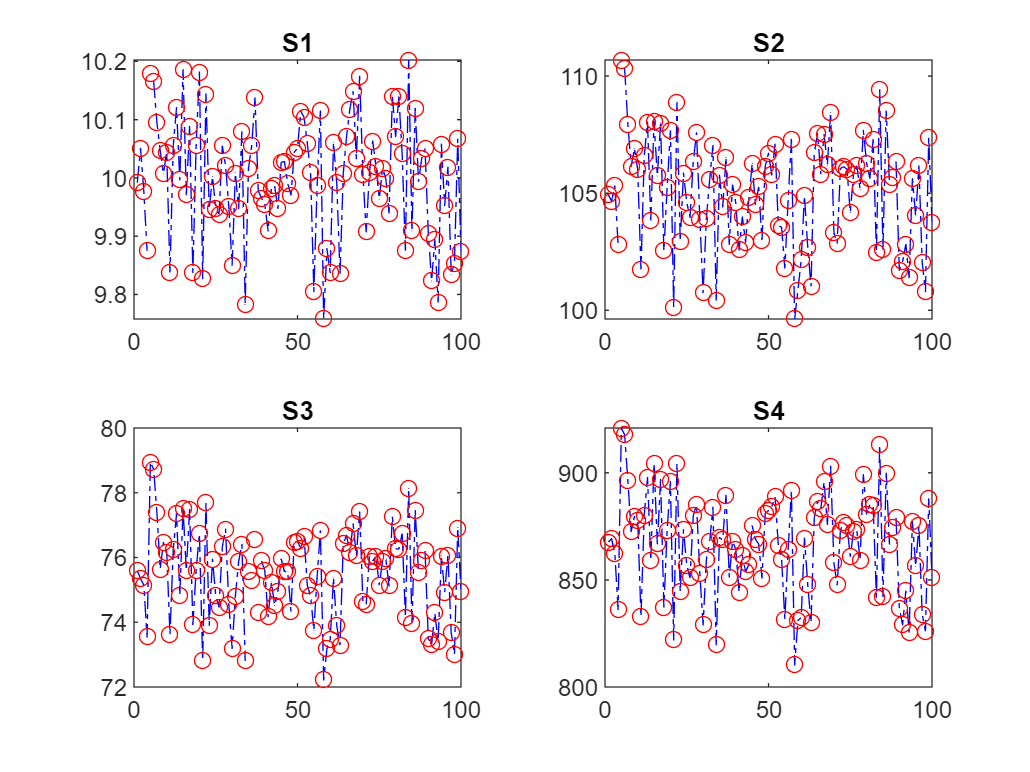

tiledlayout(2,2);

% S1
nexttile;
plot(1:100, S(:,1), 'b-.', 1:100, S_hat(:,1), 'ro');
title("S1");

% S2
nexttile;
plot(1:100, S(:,2), 'b-.', 1:100, S_hat(:,2), 'ro');
title("S2");

% S3
nexttile;
plot(1:100, S(:,3), 'b-.', 1:100, S_hat(:,3), 'ro');
title("S3");

% S4
nexttile;
plot(1:100, S(:,4), 'b-.', 1:100, S_hat(:,4), 'ro');
title("S4");